% 6G THz BPSK Signal Detection using k-NN + PCA
clc; clear;

% Parameters
N = 1e5;
SNR_dB_range = 0:2:30;
ber_baseline = zeros(size(SNR_dB_range));
ber_ML_pca = zeros(size(SNR_dB_range));
path_loss = 10;

% Generate bitstream and BPSK symbols
data = randi([0 1], N, 1);
modulated_signal = 2*data - 1;

% SNR Sweep
for i = 1:length(SNR_dB_range)
    SNR_dB = SNR_dB_range(i);
    SNR_linear = 10^(SNR_dB/10);
    noise_power = 1 / SNR_linear;
    
    % Channel: THz with AWGN
    noise_real = sqrt(noise_power/2) * randn(N, 1);
    noise_imag = sqrt(noise_power/2) * randn(N, 1);
    noise = noise_real + 1i * noise_imag;
    
    received_signal = (modulated_signal / sqrt(path_loss)) + noise;
    
    %% --- Traditional Detection (ZF)
    estimated = real(received_signal) * sqrt(path_loss);
    detected_bits = estimated > 0;
    ber_baseline(i) = sum(detected_bits ~= data) / N;
    
    %% --- ML Detection with PCA
    % Feature vector: [real, imag, magnitude]
    X = [real(received_signal), imag(received_signal), abs(received_signal)];
    Y = data;
    
    % Apply PCA to reduce dimensions
    [coeff, X_pca] = pca(X);     % coeff: eigenvectors, X_pca: projected features
    X_reduced = X_pca(:, 1:2);   % Use top 2 principal components
    
    % Split into train/test
    split_idx = floor(0.8 * N);
    X_train = X_reduced(1:split_idx, :);
    Y_train = Y(1:split_idx);
    X_test  = X_reduced(split_idx+1:end, :);
    Y_test  = Y(split_idx+1:end);

    % Train k-NN model on PCA-reduced features
    mdl = fitcknn(X_train, Y_train, ...
        'NumNeighbors', 5, ...
        'Distance', 'euclidean');

    % Predict and evaluate
    Y_pred = predict(mdl, X_test);
    ber_ML_pca(i) = sum(Y_pred ~= Y_test) / length(Y_test);

    fprintf('SNR = %2d dB | ZF = %.4f | k-NN+PCA = %.4f\n', ...
            SNR_dB, ber_baseline(i), ber_ML_pca(i));
end

SNR =  0 dB | ZF = 0.3260 | k-NN+PCA = 0.3745
SNR =  2 dB | ZF = 0.2889 | k-NN+PCA = 0.3322
SNR =  4 dB | ZF = 0.2402 | k-NN+PCA = 0.2718
SNR =  6 dB | ZF = 0.1842 | k-NN+PCA = 0.2064
SNR =  8 dB | ZF = 0.1297 | k-NN+PCA = 0.1469
SNR = 10 dB | ZF = 0.0794 | k-NN+PCA = 0.0877
SNR = 12 dB | ZF = 0.0378 | k-NN+PCA = 0.0426
SNR = 14 dB | ZF = 0.0129 | k-NN+PCA = 0.0139
SNR = 16 dB | ZF = 0.0022 | k-NN+PCA = 0.0024
SNR = 18 dB | ZF = 0.0003 | k-NN+PCA = 0.0003
SNR = 20 dB | ZF = 0.0000 | k-NN+PCA = 0.0000
SNR = 22 dB | ZF = 0.0000 | k-NN+PCA = 0.0000
SNR = 24 dB | ZF = 0.0000 | k-NN+PCA = 0.0000
SNR = 26 dB | ZF = 0.0000 | k-NN+PCA = 0.0000
SNR = 28 dB | ZF = 0.0000 | k-NN+PCA = 0.0000
SNR = 30 dB | ZF = 0.0000 | k-NN+PCA = 0.0000


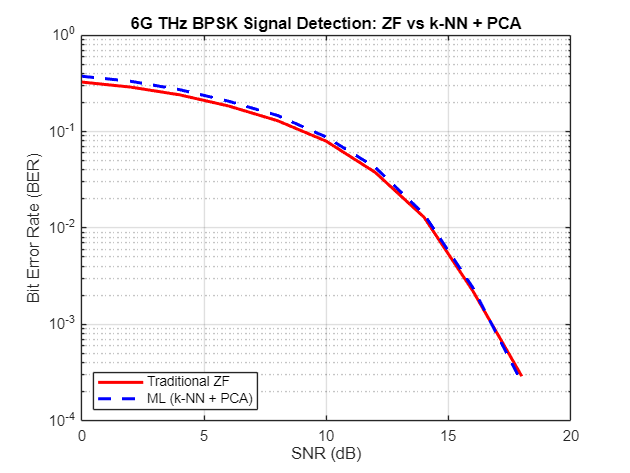


%% --- Plot Results
figure;
semilogy(SNR_dB_range, ber_baseline, 'r-', 'LineWidth', 2); hold on;
semilogy(SNR_dB_range, ber_ML_pca, 'b--', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('6G THz BPSK Signal Detection: ZF vs k-NN + PCA');
legend('Traditional ZF', 'ML (k-NN + PCA)', 'Location', 'southwest');
grid on;
ylim([1e-4 1]);
saveas(gcf, 'knn+pca.eps', 'epsc');  % 'epsc' for color EPS